clearvars -except tMax_a tMax_c tMax_b Fz_arfada Fbeta Ftheta_c theta1 P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada


## Arfada

### Caso 1: Arfada simple

ts=linspace(0,tMax_a,50);
balanceo=0;
cabeceo=0;
arfada=Fz_arfada;
largoB=0.4;
largoM=0.2;
AlturaPlaca=0.6;
PosXBiela=0.1;
PosYBiela=-0.418;
PosXEje=0;
PosYEje=-0.414;
PosZEje=0.2;

%theta1
FthetaArfada=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB cabeceo balanceo arfada]);
FthetaArfadaW=diff(FthetaArfada);
FthetaArfadaAlpha=diff(FthetaArfadaW);
%plot(t,Ftheta())

#### Valores arfada

angulosArfada=double(subs(FthetaArfada,ts));
VelocidadAngularArfada=double(subs(FthetaArfadaW,ts));
AceleracionAngularArfada=double(subs(FthetaArfadaAlpha,ts));

#### Gráficas arfada

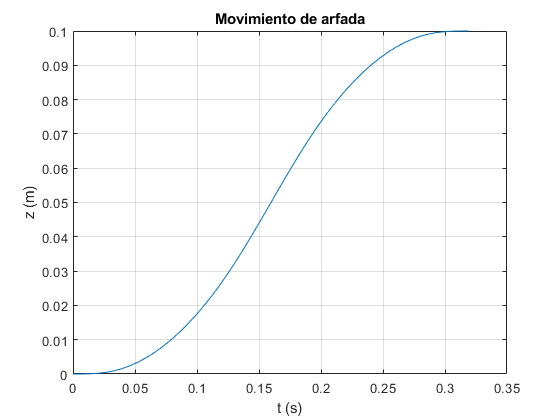

figure()
plot(ts,arfada(ts))
title('Movimiento de arfada')
grid on
xlabel('t (s)')
ylabel('z (m)')

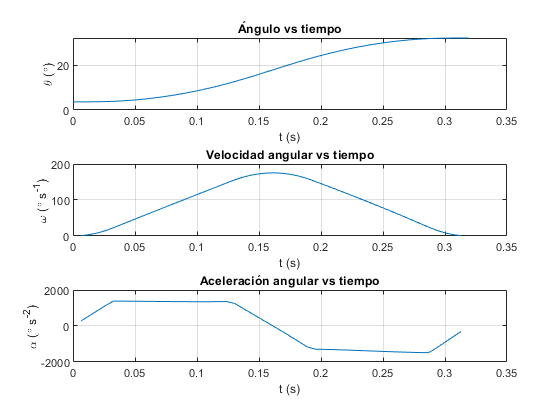


figure('Name','Cinematica manivela en arfada caso 1')
subplot(3,1,1)
plot(ts,angulosArfada.*180./pi)
title('Ángulo vs tiempo')
xlabel('t (s)')
ylabel('\theta (\circ)')
grid on
subplot(3,1,2)
plot(ts,VelocidadAngularArfada.*180./pi)
title('Velocidad angular vs tiempo')
xlabel('t (s)')
ylabel('\omega (\circ s^{-1})')
grid on
subplot(3,1,3)
plot(ts,AceleracionAngularArfada.*180./pi)
title('Aceleración angular vs tiempo')
xlabel('t (s)')
ylabel('\alpha (\circ s^{-2})')
grid on

### Caso 2: Balanceo y cabeceo máximos

ts=linspace(0,tMax_a,50);
balanceo=15*pi/180;
cabeceo=18*pi/180;
arfada=Fz_arfada;
largoB=0.4;
largoM=0.2;
AlturaPlaca=0.6;
PosXBiela=0.1;
PosYBiela=-0.418;
PosXEje=0;
PosYEje=-0.414;
PosZEje=0.2;

FthetaArfada=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB cabeceo balanceo arfada]);
FthetaArfadaW=diff(FthetaArfada);
FthetaArfadaAlpha=diff(FthetaArfadaW);


#### Valores arfada

angulosArfada=double(subs(FthetaArfada,ts));
VelocidadAngularArfada=double(subs(FthetaArfadaW,ts));
AceleracionAngularArfada=double(subs(FthetaArfadaAlpha,ts));

#### Gráficas arfada

figure()
plot(ts,arfada(ts))
title('Movimiento de arfada')
grid on
xlabel('t (s)')
ylabel('z (m)')

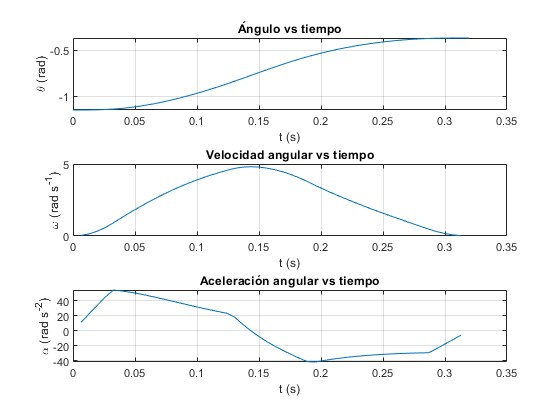


figure('Name','Cinematica manivela en arfada caso 2')
subplot(3,1,1)
plot(ts,angulosArfada.*180./pi)
title('Ángulo vs tiempo')
xlabel('t (s)')
ylabel('\theta (\circ)')
grid on
subplot(3,1,2)
plot(ts,VelocidadAngularArfada.*180./pi)
title('Velocidad angular vs tiempo')
xlabel('t (s)')
ylabel('\omega (\circ s^{-1})')
grid on
subplot(3,1,3)
plot(ts,AceleracionAngularArfada.*180./pi)
title('Aceleración angular vs tiempo')
xlabel('t (s)')
ylabel('\alpha (\circ s^{-2})')
grid on

### Caso 3: Balanceo y cabeceo mínimos

ts=linspace(0,tMax_a,50);
balanceo=-15*pi/180;
cabeceo=-18*pi/180;
arfada=Fz_arfada;
largoB=0.4;
largoM=0.2;
AlturaPlaca=0.6;
PosXBiela=0.1;
PosYBiela=-0.418;
PosXEje=0;
PosYEje=-0.414;
PosZEje=0.2;
%theta1
FthetaArfada=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB cabeceo balanceo arfada]);
FthetaArfadaW=diff(FthetaArfada);
FthetaArfadaAlpha=diff(FthetaArfadaW);
%plot(t,Ftheta())

#### Valores arfada

angulosArfada=double(subs(FthetaArfada,ts));
VelocidadAngularArfada=double(subs(FthetaArfadaW,ts));
AceleracionAngularArfada=double(subs(FthetaArfadaAlpha,ts));

#### Gráficas arfada

figure()
plot(ts,arfada(ts))
title('Movimiento de arfada')
grid on
xlabel('t (s)')
ylabel('z (m)')

figure('Name','Cinematica manivela en arfada caso 3')
subplot(3,1,1)
plot(ts,angulosArfada.*180./pi)
title('Ángulo vs tiempo')
xlabel('t (s)')
ylabel('\theta (\circ)')
grid on
subplot(3,1,2)
plot(ts,VelocidadAngularArfada.*180./pi)
title('Velocidad angular vs tiempo')
xlabel('t (s)')
ylabel('\omega (\circ s^{-1})')
grid on
subplot(3,1,3)
plot(ts,AceleracionAngularArfada.*180./pi)
title('Aceleración angular vs tiempo')
xlabel('t (s)')
ylabel('\alpha (\circ s^{-2})')
grid on

## Cabeceo

### Caso 1: Balanceo y arfada nula

ts=linspace(0,tMax_c,50);
balanceo=0; %valor de balanceo en radianes
cabeceo=Ftheta_c;
arfada=0; %valor de arfada
largoB=0.4;
largoM=0.2;
AlturaPlaca=0.6;
PosXBiela=0.1;
PosYBiela=-0.418;
PosXEje=0;
PosYEje=-0.414;
PosZEje=0.2;
%theta1
FthetaCabeceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB cabeceo balanceo arfada]);
FthetaCabeceoW=diff(FthetaCabeceo);
FthetaCabeceoAlpha=diff(FthetaCabeceoW);
%plot(t,Ftheta())

#### Valores cabeceo

angulosCabeceo=subs(FthetaCabeceo,ts);
VelocidadAngularCabeceo=subs(FthetaCabeceoW,ts);
AceleracionAngularCabeceo=subs(FthetaCabeceoAlpha,ts);


#### Gráficas cabeceo

figure()
plot(ts,cabeceo(ts))
title('Movimiento de cabeceo')
xlabel('t (s)')
ylabel('\theta (rad)')
grid on
figure('Name','Cinematica manivela en cabeceo caso 1')
subplot(3,1,1)
plot(ts,angulosCabeceo.*180./pi)
title('Ángulo vs tiempo')
xlabel('t (s)')
ylabel('\theta (\circ)')
grid on
subplot(3,1,2)
plot(ts,VelocidadAngularCabeceo.*180./pi)
title('Velocidad angular vs tiempo')
xlabel('t (s)')
ylabel('\omega (\circ s^{-1})')
grid on
subplot(3,1,3)
plot(ts,AceleracionAngularCabeceo.*180./pi)
title('Aceleración angular vs tiempo')
xlabel('t (s)')
ylabel('\alpha (\circ s^{-2})')
grid on

### Caso 2: Balanceo máximo, arfada nula

ts=linspace(0,tMax_c,50);
balanceo=15*pi/180; %valor de balanceo en radianes
cabeceo=Ftheta_c;
arfada=0; %valor de arfada
largoB=0.4;
largoM=0.2;
AlturaPlaca=0.6;
PosXBiela=0.1;
PosYBiela=-0.418;
PosXEje=0;
PosYEje=-0.414;
PosZEje=0.2;
%theta1
FthetaCabeceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB cabeceo balanceo arfada]);
FthetaCabeceoW=diff(FthetaCabeceo);
FthetaCabeceoAlpha=diff(FthetaCabeceoW);
%plot(t,Ftheta())

#### Valores cabeceo

angulosCabeceo=subs(FthetaCabeceo,ts);
VelocidadAngularCabeceo=subs(FthetaCabeceoW,ts);
AceleracionAngularCabeceo=subs(FthetaCabeceoAlpha,ts);


#### Gráficas cabeceo

figure()
plot(ts,cabeceo(ts))
title('Movimiento de cabeceo')
xlabel('t (s)')
ylabel('\theta (rad)')
grid on
figure('Name','Cinematica manivela en cabeceo caso 1')
subplot(3,1,1)
plot(ts,angulosCabeceo.*180./pi)
title('Ángulo vs tiempo')
xlabel('t (s)')
ylabel('\theta (\circ)')
grid on
subplot(3,1,2)
plot(ts,VelocidadAngularCabeceo.*180./pi)
title('Velocidad angular vs tiempo')
xlabel('t (s)')
ylabel('\omega (\circ s^{-1})')
grid on
subplot(3,1,3)
plot(ts,AceleracionAngularCabeceo.*180./pi)
title('Aceleración angular vs tiempo')
xlabel('t (s)')
ylabel('\alpha (\circ s^{-2})')
grid on

### Caso 3: Balanceo minimo, arfada máxima 

ts=linspace(0,tMax_c,50);
balanceo=-15*pi/180; %valor de balanceo en radianes
cabeceo=Ftheta_c;
arfada=0.1; %valor de arfada
largoB=0.4;
largoM=0.2;
AlturaPlaca=0.6;
PosXBiela=0.1;
PosYBiela=-0.418;
PosXEje=0;
PosYEje=-0.414;
PosZEje=0.2;

FthetaCabeceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB cabeceo balanceo arfada]);
FthetaCabeceoW=diff(FthetaCabeceo);
FthetaCabeceoAlpha=diff(FthetaCabeceoW);


#### Valores cabeceo

angulosCabeceo=subs(FthetaCabeceo,ts);
VelocidadAngularCabeceo=subs(FthetaCabeceoW,ts);
AceleracionAngularCabeceo=subs(FthetaCabeceoAlpha,ts);


#### Gráficas cabeceo

figure()
plot(ts,cabeceo(ts))
title('Movimiento de cabeceo')
grid on
figure('Name','Cinematica manivela en cabeceo caso 2')
subplot(3,1,1)
plot(ts,angulosCabeceo.*180./pi)
title('Ángulo vs tiempo')
xlabel('t (s)')
ylabel('\theta (\circ)')
grid on
subplot(3,1,2)
plot(ts,VelocidadAngularCabeceo.*180./pi)
title('Velocidad angular vs tiempo')
xlabel('t (s)')
ylabel('\omega (\circ s^{-1})')
grid on
subplot(3,1,3)
plot(ts,AceleracionAngularCabeceo.*180./pi)
title('Aceleración angular vs tiempo')
xlabel('t (s)')
ylabel('\alpha (\circ s^{-2})')
grid on

## Balanceo

### Caso 1: Cabeceo y arfada nula 

ts=linspace(0,tMax_b,50);
balanceo=Fbeta; %valor de balanceo en radianes
cabeceo=0; %valor cabeceo en radianes
arfada=0; %valor de arfada

largoB=0.4;
largoM=0.2;
AlturaPlaca=0.6;
PosXBiela=0.1;
PosYBiela=-0.418;
PosXEje=0;
PosYEje=-0.414;
PosZEje=0.2;

FthetaBalanceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB cabeceo balanceo arfada]);
FthetaBalanceoW=diff(FthetaBalanceo);
FthetaBalanceoAlpha=diff(FthetaBalanceoW);


#### Valores balanceo

angulosBalanceo=subs(FthetaBalanceo,ts);
VelocidadAngularBalanceo=subs(FthetaBalanceoW,ts);
AceleracionAngularBalanceo=subs(FthetaBalanceoAlpha,ts);


#### Gráficas balanceo


figure()
plot(ts,balanceo(ts))
title('Movimiento de balanceo')
grid on
xlabel('t (s)')
ylabel('\beta (rad)')

figure('Name','Cinematica manivela en balanceo caso 1')
subplot(3,1,1)
plot(ts,angulosBalanceo.*180./pi)
title('Ángulo vs tiempo')
xlabel('t (s)')
ylabel('\theta (\circ)')
grid on
subplot(3,1,2)
plot(ts,VelocidadAngularBalanceo.*180./pi)
title('Velocidad angular vs tiempo')
xlabel('t (s)')
ylabel('\omega (\circ s^{-1})')
grid on
subplot(3,1,3)
plot(ts,AceleracionAngularBalanceo.*180./pi)
title('Aceleración angular vs tiempo')
xlabel('t (s)')
ylabel('\alpha (\circ s^{-2})')
grid on

### Caso 2: Cabeceo máximo, arfada nula 

ts=linspace(0,tMax_b,50);
balanceo=Fbeta; %valor de balanceo en radianes
cabeceo=18*pi/180; %valor cabeceo en radianes
arfada=0; %valor de arfada

largoB=0.4;
largoM=0.2;
AlturaPlaca=0.6;
PosXBiela=0.1;
PosYBiela=-0.418;
PosXEje=0;
PosYEje=-0.414;
PosZEje=0.2;

FthetaBalanceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB cabeceo balanceo arfada]);
FthetaBalanceoW=diff(FthetaBalanceo);
FthetaBalanceoAlpha=diff(FthetaBalanceoW);


#### Valores balanceo

angulosBalanceo=subs(FthetaBalanceo,ts);
VelocidadAngularBalanceo=subs(FthetaBalanceoW,ts);
AceleracionAngularBalanceo=subs(FthetaBalanceoAlpha,ts);


#### Gráficas balanceo


figure()
plot(ts,balanceo(ts))
title('Movimiento de balanceo')
grid on
xlabel('t (s)')
ylabel('\beta (rad)')

figure('Name','Cinematica manivela en balanceo caso 1')
subplot(3,1,1)
plot(ts,angulosBalanceo.*180./pi)
title('Ángulo vs tiempo')
xlabel('t (s)')
ylabel('\theta (\circ)')
grid on
subplot(3,1,2)
plot(ts,VelocidadAngularBalanceo.*180./pi)
title('Velocidad angular vs tiempo')
xlabel('t (s)')
ylabel('\omega (\circ s^{-1})')
grid on
subplot(3,1,3)
plot(ts,AceleracionAngularBalanceo.*180./pi)
title('Aceleración angular vs tiempo')
xlabel('t (s)')
ylabel('\alpha (\circ s^{-2})')
grid on

### Caso 3: Cabeceo minimo, arfada máxima

ts=linspace(0,tMax_b,50);
balanceo=Fbeta; %valor de balanceo en radianes
cabeceo=-18*pi/180;
arfada=0.1; %valor de arfada

largoB=0.4;
largoM=0.2;
AlturaPlaca=0.6;
PosXBiela=0.1;
PosYBiela=-0.418;
PosXEje=0;
PosYEje=-0.414;
PosZEje=0.2;
%theta1
FthetaBalanceo=subs(theta1,[P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada],[AlturaPlaca PosXBiela PosYBiela PosXEje PosYEje PosZEje largoM largoB cabeceo balanceo arfada]);
FthetaBalanceoW=diff(FthetaBalanceo);
FthetaBalanceoAlpha=diff(FthetaBalanceoW);
%plot(t,Ftheta())

#### Valores balanceo

angulosBalanceo=subs(FthetaBalanceo,ts);
VelocidadAngularBalanceo=subs(FthetaBalanceoW,ts);
AceleracionAngularBalanceo=subs(FthetaBalanceoAlpha,ts);


#### Gráficas balanceo

figure()
plot(ts,balanceo(ts))
xlabel('t (s)')
ylabel('\beta (rad)')
title('Movimiento de balanceo')
grid on
figure('Name','Cinematica manivela en balanceo caso 2')
subplot(3,1,1)
plot(ts,angulosBalanceo.*180./pi)
title('Ángulo vs tiempo')
xlabel('t (s)')
ylabel('\theta (\circ)')
grid on
subplot(3,1,2)
plot(ts,VelocidadAngularBalanceo.*180./pi)
title('Velocidad angular vs tiempo')
xlabel('t (s)')
ylabel('\omega (\circ s^{-1})')
grid on
subplot(3,1,3)
plot(ts,AceleracionAngularBalanceo.*180./pi)
title('Aceleración angular vs tiempo')
xlabel('t (s)')
ylabel('\alpha (\circ s^{-2})')
grid on